Sensordata = load('My_data_frfr_final_frfinal_claim.csv');
Sensordata = Sensordata(70:230,:);

speed_func = @(u) ((27531009*abs(sin((53*u)./20 + 371/100)).^2)./1562500 + (9801*abs(cos(u + 7/5)).^2)./625).^(1/2);
q = integral(speed_func, 0, 3.2) / 3.2;
beta = 1/5;
max_speed = q/beta;

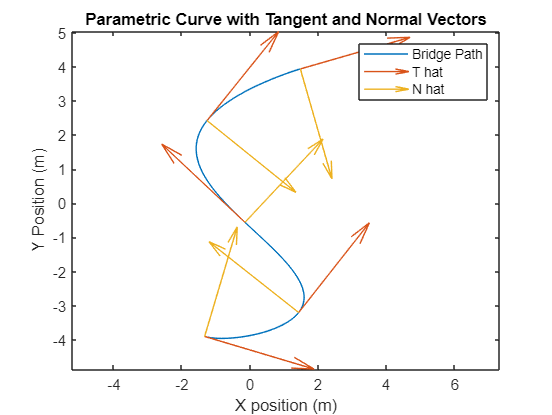

u = linspace(0, 3.2, 100);
x = 4*(0.396*cos(2.65*(u + 1.4)));
y = -4*0.99*(sin(u + 1.4));

plot(x, y)
hold on
u = linspace(0, 3.2, 5);
x = 4*(0.396*cos(2.65*(u + 1.4)));
y = -4*0.99*(sin(u + 1.4));
T_hat_x = -(53*sin((53*u)./20 + 371/100))./(2809*sin((53*u)./20 + 371/100).^2 + 2500*cos(u + 7/5).^2).^(1/2);
T_hat_y = -(50*cos(u + 7/5))./(2809*sin((53*u)./20 + 371/100).^2 + 2500*cos(u + 7/5).^2).^(1/2);
quiver(x, y, T_hat_x, T_hat_y)
N_hat_x = -(2*(483625*cos((13*u)./20 + 91/100) + 702250*cos((53*u)./20 + 371/100) + 218625*cos((93*u)./20 + 651/100)))./(265*(2809*(40*sin(u + 7/5) + 73*sin((43*u)./10 + 301/50) + 33*sin((63*u)./10 + 441/50)).^2 + 2500*(73*cos((13*u)./20 + 91/100) + 106*cos((53*u)./20 + 371/100) + 33*cos((93*u)./20 + 651/100)).^2).^(1/2));
N_hat_y = (561800*sin(u + 7/5) + 1025285*sin((43*u)./10 + 301/50) + 463485*sin((63*u)./10 + 441/50))./(265*(2809*(40*sin(u + 7/5) + 73*sin((43*u)./10 + 301/50) + 33*sin((63*u)./10 + 441/50)).^2 + 2500*(73*cos((13*u)./20 + 91/100) + 106*cos((53*u)./20 + 371/100) + 33*cos((93*u)./20 + 651/100)).^2).^(1/2));
quiver(x, y, N_hat_x, N_hat_y)
legend(["Bridge Path", "T hat", "N hat"])
title("Parametric Curve with Tangent and Normal Vectors")
xlabel("X position (m)")
ylabel("Y Position (m)")
axis equal
hold off

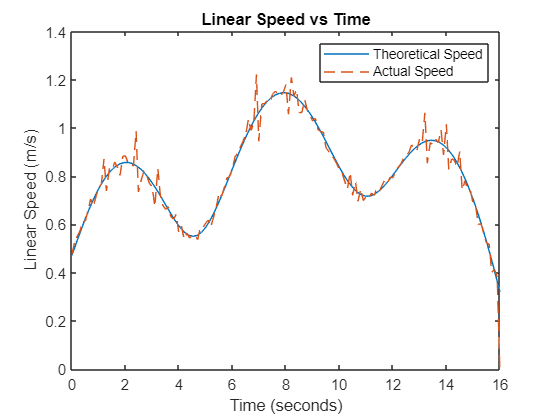

u = linspace(0, 3.2, 100);
x = 4*(0.396*cos(2.65*(u + 1.4)));
y = -4*0.99*(sin(u + 1.4));
T_hat_x = -(53*sin((53*u)./20 + 371/100))./(2809*sin((53*u)./20 + 371/100).^2 + 2500*cos(u + 7/5).^2).^(1/2);
T_hat_y = -(50*cos(u + 7/5))./(2809*sin((53*u)./20 + 371/100).^2 + 2500*cos(u + 7/5).^2).^(1/2);
speed = ((27531009*abs(sin((53*u)./20 + 371/100)).^2)./1562500 + (9801*abs(cos(u + 7/5)).^2)./625).^(1/2);
plot(u./beta, speed.*beta)
hold on
plot(time, Vlinear, '--')
xlabel("Time (seconds)")
ylabel("Linear Speed (m/s)")
title("Linear Speed vs Time")
legend("Theoretical Speed", "Actual Speed")
hold off

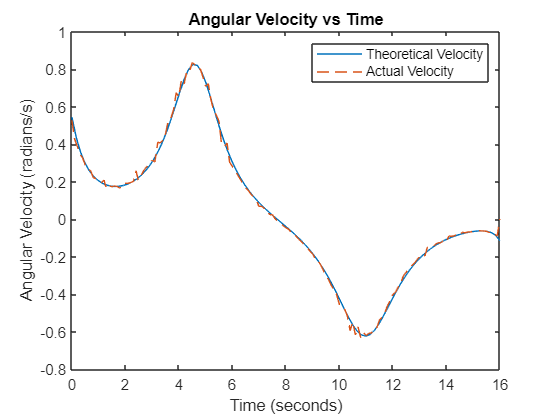


T_hat_prime_x = (53.*sin((53.*u)./20 + 371/100).*((148877.*cos((53.*u)./20 + 371/100).*sin((53.*u)./20 + 371/100))./10 - 5000.*cos(u + 7/5).*sin(u + 7/5)))./(2*(2809*sin((53*u)./20 + 371/100).^2 + 2500.*cos(u + 7/5).^2).^(3/2)) - (2809.*cos((53*u)./20 + 371/100))./(20*(2809.*sin((53*u)./20 + 371/100).^2 + 2500*cos(u + 7/5).^2).^(1/2));
T_hat_prime_y = (50.*sin(u + 7/5))./(2809.*sin((53*u)./20 + 371/100).^2 + 2500.*cos(u + 7/5).^2).^(1/2) + (25.*cos(u + 7/5).*((148877.*cos((53.*u)./20 + 371/100).*sin((53*u)./20 + 371/100))./10 - 5000.*cos(u + 7/5).*sin(u + 7/5)))./(2809.*sin((53*u)./20 + 371/100).^2 + 2500.*cos(u + 7/5).^2).^(3/2);
T_hat_prime = [T_hat_prime_x; T_hat_prime_y; zeros(1,100)];
omega = cross([T_hat_x; T_hat_y; zeros(1, 100)], T_hat_prime);
plot(u./beta, omega(3,:).*beta)
hold on
plot(time, Vangular, '--')
xlabel("Time (seconds)")
ylabel("Angular Velocity (radians/s)")
title("Angular Velocity vs Time")
legend("Theoretical Velocity", "Actual Velocity")
hold off

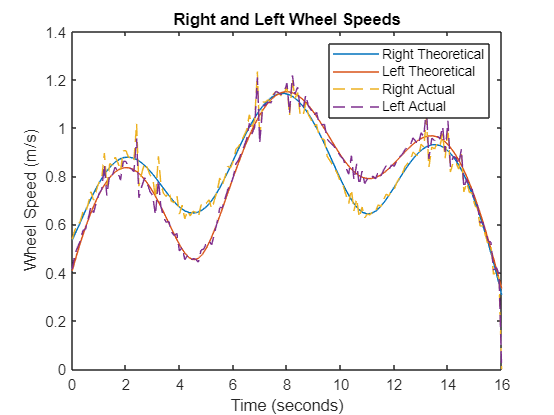

Vx = -(5247.*sin((53*u)./20 + 371/100))./1250;
Vy = -(99.*cos(u + 7/5))./25;
V = (Vx.^2 + Vy.^2).^0.5;
vL = V - omega(3,:).*0.235./2;
vR = V + omega(3,:).*0.235./2;
plot(u./beta, vR.*beta)
hold on
plot(u./beta, vL.*beta)
plot(time, rVelocity, '--')
plot(time, lVelocity, '--')
legend(["Right Theoretical", "Left Theoretical", "Right Actual", "Left Actual"])
xlabel("Time (seconds)")
ylabel("Wheel Speed (m/s)")
title("Right and Left Wheel Speeds")
hold off

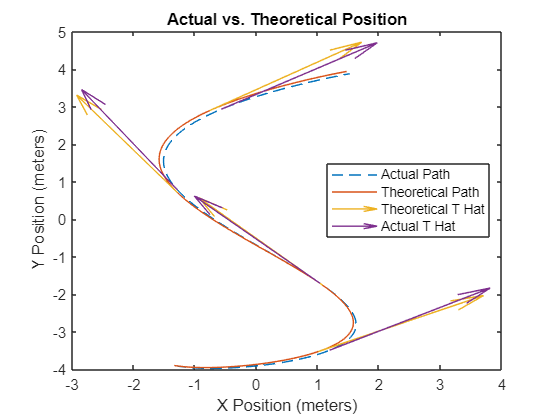

time = Sensordata(:,1) - Sensordata(1,1);
deltaT = time(2:end)-time(1:end-1);
leftWheelSensor = Sensordata(:,2) - Sensordata(1,2);
rightWheelSensor = Sensordata(:,3) - Sensordata(1,3);
PositionX = zeros(size(time));
PositionX(1) = -1.33493081667057;
PositionY = zeros(size(time));
PositionY(1) = -3.90238093075430;
orientation = zeros(size(time));
orientation(1) = -pi/10;
lVelocity = zeros(size(time));
rVelocity = zeros(size(time));
for i = 1:size(deltaT)
    lVelocity(i) = (leftWheelSensor(i+1)-leftWheelSensor(i))/deltaT(i);
    rVelocity(i) = (rightWheelSensor(i+1)-rightWheelSensor(i))/deltaT(i);
end
Vlinear = (lVelocity+rVelocity)/2;
Vangular = (rVelocity-lVelocity)/0.235;
for i = 2:size(time)
    orientation(i) = orientation(i-1) + Vangular(i-1)* deltaT(i-1);
    PositionX(i) = PositionX(i-1) + Vlinear(i-1) * cos(orientation(i-1)) * deltaT(i-1);
    PositionY(i) = PositionY(i-1) + Vlinear(i-1) * sin(orientation(i-1)) * deltaT(i-1);
    
end


clf;
plot(PositionX, PositionY, '--')
hold on
plot(x,y)
u = linspace(0, 3.2, 6);
u = u(2:end-1);
x = 4*(0.396*cos(2.65*(u + 1.4)));
y = -4*0.99*(sin(u + 1.4));
T_hat_x = -(53*sin((53*u)./20 + 371/100))./(2809*sin((53*u)./20 + 371/100).^2 + 2500*cos(u + 7/5).^2).^(1/2);
T_hat_y = -(50*cos(u + 7/5))./(2809*sin((53*u)./20 + 371/100).^2 + 2500*cos(u + 7/5).^2).^(1/2);
quiver(x, y, T_hat_x, T_hat_y)
vectorIndeces = zeros(size(y));
for i = 1:4
    for j = 1:size(time)
        if y(i)<PositionY(j) & (vectorIndeces(i) == 0)
            vectorIndeces(i) = j;
        end
  
    end
end
Actual_T_x = (PositionX(vectorIndeces)-PositionX(vectorIndeces - 1))./deltaT(vectorIndeces-1);
Actual_T_y = (PositionY(vectorIndeces)-PositionY(vectorIndeces - 1))./deltaT(vectorIndeces-1);
magnitude = (Actual_T_y .^ 2 + Actual_T_x .^ 2).^ 0.5;
Actual_T_hat_x = Actual_T_x ./ magnitude;
Actual_T_hat_y = Actual_T_y ./ magnitude;
quiver(PositionX(vectorIndeces), PositionY(vectorIndeces), Actual_T_hat_x, Actual_T_hat_y)
legend("Actual Path", "Theoretical Path", "Theoretical T Hat", "Actual T Hat", 'Location', 'East')
xlabel("X Position (meters)")
ylabel("Y Position (meters)")
title("Actual vs. Theoretical Position")